clc;
clearvars;

Variables:

P3Q2_LPC = 3;
P3Q2_HPC = 5;
y_c = 1.4;
y_t = 1.33;
M = 0.2;
ETHA_Comp = 0.8;
ETHA_Comb = 0.95;
T4 = 1600;
Cp_hot = 1150;
Cp_cold = 1000;
LCV = 43 * 10^6;
ETHA_turb = 0.85;
R = 287.5;

Height input, temperature and pressure output:

h = [0, 250, 500, 750, 1000, 1250, 1500, 1750, 2000, 2250, 2500, 2750, 3000, 3500, 4000, 4500, 5000, 6000, 7000, 8000, 9000, 10000, 20000, 30000, 40000];

Pb = 101.325;
Tb = 288.2;
hb = 0;
Lb = 0.0065;
g = 9.80665;
Mol = 0.0289644;
R1 = 8.3144598;
P0 = Pb * ((Tb - (h - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb));

T0 = Tb - (h * Lb);

Intake conditions:

W0 = 100;

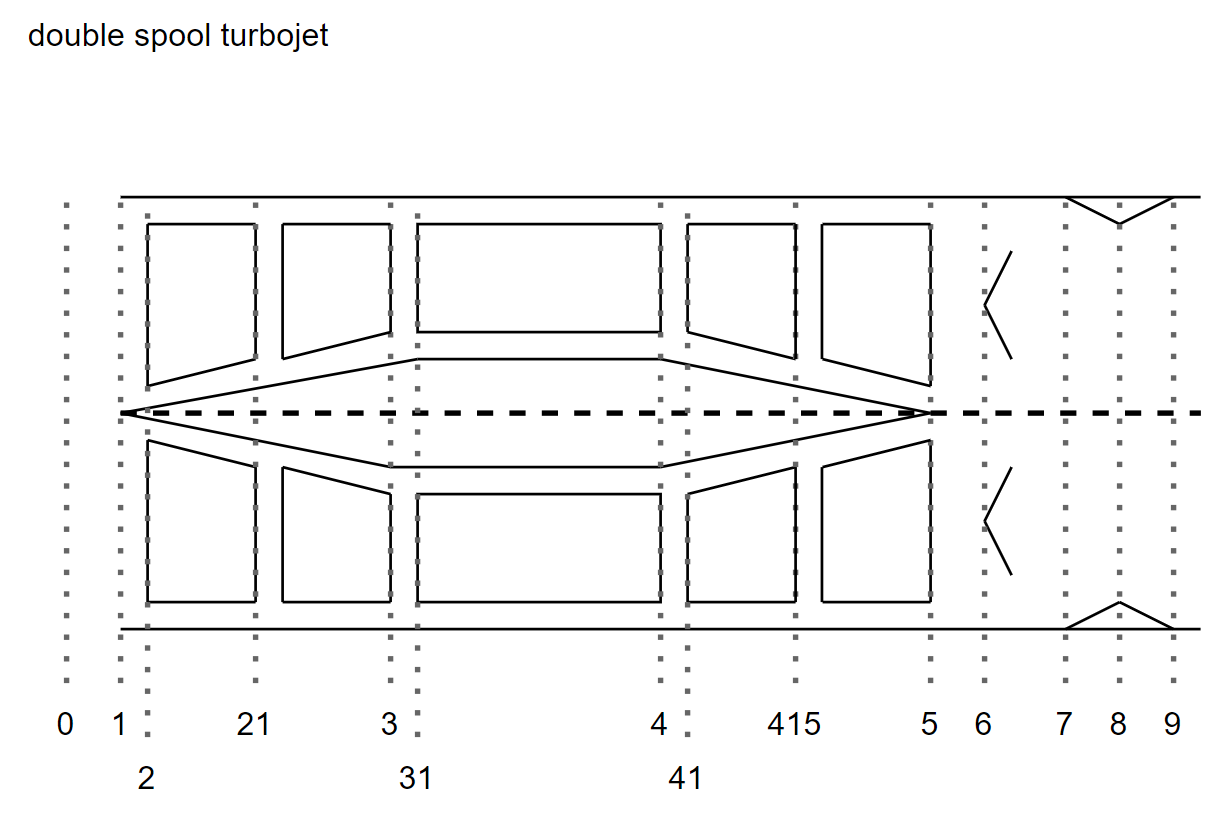

**Station 0: Atmospheric**

T0;
P0;
W0;

**Station 1: Inlet**

T1 = T0;
P1 = P0;
W1 = W0;

**Station 2: LPC (low pressure compressor) inlet**

T2 = T1 * (1 + ((y_c-1)/2) * M^2);
P2 = P1 * (T2/T0)^(y_c/(y_c-1));
W2 = W1;                            % Nothing is added to the flow

**Station 21: LPC**

P21 = P2 * P3Q2_LPC;
T21 = T2 * (1 + ((P21/P2)^((y_c - 1)/y_c)- 1)/ETHA_Comp);
W21 = W2;                           % Nothing is added to the flow

**Station 3: HPC (high pressure compressor) outlet**

P3 = P21 * P3Q2_HPC;
T3 = T21 * (1 + ((P3/P21)^((y_c - 1)/y_c)- 1)/ETHA_Comp);
W3 = W21;                           % Nothing is added to the flow

**Station 31 Combuster inlet**

P31 = P3;
T31 = T3;
W31 = W3;

**Station 4: Combustor outlet**

P4 = P31 * ETHA_Comb;
T4;
Q = W31 * Cp_hot * (T4 - T31);
WF = Q/LCV;
W4 = WF + W31;

**Station 41: HPT (high pressure turbine) inlet**

WHPC = W3 * Cp_cold * (T3 - T21);
T41 = T4 - (WHPC./(W4.* Cp_hot));
P41 = P4.* (1- (1-(T41./T3))/ETHA_turb).^(y_t/(y_t- 1));
W41 = W4;                           % Nothing is added to the flow

**Station 415: LPT (low pressure turbine) inlet**

WLPC = W2 * Cp_cold * (T21 - T0);
T415 = T41 - (WLPC./(W4.* Cp_hot));
P415 = P41 * (1 - (1-(T415/T41))/ ETHA_turb)^(y_t/(y_t- 1));
W415 = W41;                           % Nothing is added to the flow

**Station 5: LPT outlet **

T5 = T415;
P5 = P415;
W5 = W415;

**Calculating static conditions:**

Ps = P5/(1 + (y_c - 1)/2)^(y_c/(y_c-1));
Ts = T5/(1 + (y_c - 1)/2);

**Calculating Jet Velocity:**

Vj = sqrt(y_c * R *Ts);

**Calculate static density:**

rho = (Ps.*1000)./(Ts.*R);

**Calculate nozzle area required:**

An = W0./(Vj.*rho);

**Calculate Thrust: (N)**

Fn = (W0 + WF).* Vj + An.* (Ps - P0);

**Calculate SFC (specific fuel consumption): (g/s kN)**

SFC = (WF./Fn).* 1000000;

**Calculate ETATH (thermal efficiency):**

ETATH = 100.*(3600./(SFC.*(LCV/10^5)));

**Plots:**

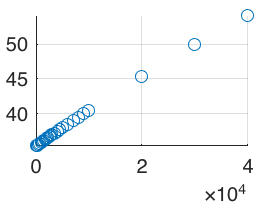

s1 = scatter (h, SFC);
grid on;

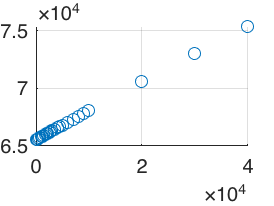


s2 = scatter (h, Fn);
grid on;

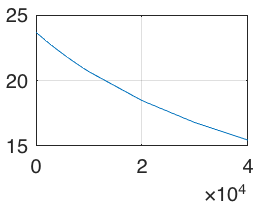


s3 = plot (h, ETATH);
grid on;